# Lab 2 Template

This is an mlx (matlab live script) template for the labs. Live Script allows you to mix code with text. Try to structure you code with one cell/section per exercise and keep all functions in the ./functions directory and all images in the ./images directory.

## Setting up environment

Here we clear old variables and make sure that ./functions and ./images are in the path.

% use clear to avoid unknowingly being dependent on 
% variables in the workspace defined by other scripts
% or in the command window
clear;

%add ./functions and ./images folders to path
%addpath('./functions');
%addpath('./images');

#### Command shortlist:

- "%% Exercise 3": Create a new section called "Exercise 3"

- ctrl+shift+enter: Run section

- ctrl+e:  Switch between text and code mode for selected lines

- ctrl+E: Write equation (syntax similar to latex math)

## Exercise 2.1

Press ctrl+shift+enter to run this section.

%% 2.1 Learning a linear classifier
clear;
clc;
% Ex 2.1 - Load data
 load ('cell_data.mat')
%load stuff_for_lab_2/cell_data.mat;
% positive patches denoted as fg_patches
% negative patches denoted as bg_patches

% Ex 2.2 - Creation of two new variables
% Examples: a cell structure containing the all the patches (both positives and negatives)
fg_cells= cell_data.fg_patches; 
bg_cells= cell_data.bg_patches;
% 

examples={}; 
examples(1:length(fg_cells))= fg_cells; 
examples(length(fg_cells)+1:400)= bg_cells;
% cell_data.examples = zeros(1,length(cell_data.fg_patches)+length(cell_data.fg_patches));
% cell_data.labels = zeros(1,length(cell_data.fg_patches)+length(cell_data.fg_patches));

% (1,400) vector
%cell_data.examples = [cell_data.fg_patches cell_data.bg_patches];

% (1,400) vector
%cell_data.labels = [ones(1,200) zeros(1,200)];

for i= 1: length(fg_cells)
    labels(i)= 1;
end 

for i= (length(fg_cells)+1) : (length(fg_cells) + length(bg_cells))
    labels(i)=0; 
end 

%% 2.3 splitting into training and validataion data 
% distrubution is 50% 25% 25%, between training, testing, validation
% Models with very few hyperparameters will be easy to validate and tune, 
%so you can probably reduce the size of your validation set, but if your 
%model has many hyperparameters, you would want to have a large validation 
%set as well(although you should also consider cross validation).
clc


examples_train(1:100)=examples(1:100); % selection of 100 good cells for training
examples_train(101:200)=examples(201:300); % selection of 100 bad cells for training
labels_train(1:100)= labels(1:100); 
labels_train(101:200)= labels(201:300); 


examples_test(1:50)=examples(101:150); % selection of 50 good cells for testing
examples_test(51:100)=examples(301:350); % selection of 50 bad cells for testing
labels_test(1:50)= labels(101:150); 
labels_test(51:100)= labels(301:350); 

examples_val(1:50)= examples(151:200);% selection of 50 good cells for validataion
examples_val(51:100)=examples(351:400); % selection of 50 bad cells for validation
labels_val(1:50)= labels(151:200); 
labels_val(51:100)= labels(351:400);



## Exercise 2.4 and 2.5

Plots are also shown to the right.

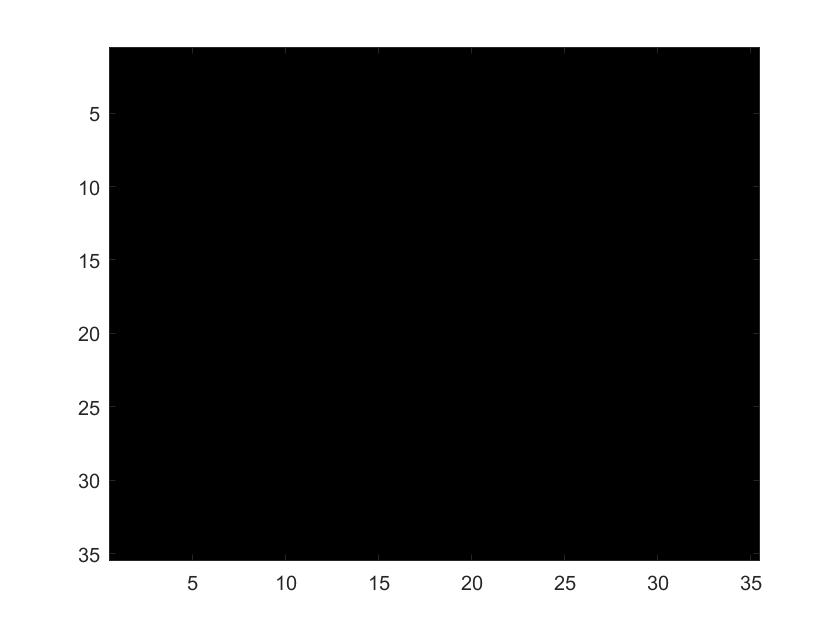

%% 2.4
%function file for partial_gradient is created, see partial_gradient.m

%% 2.5
%function file for process_epoch is created, see process_epoch.m



clc
close all 

s = 0.01; 
w = s * randn(35,35);% a random wighted gray 35,35 img
w0 = 0;
lrate= 4; % sets the steplength for the gradient decent
w0_decent= []; 
w_decent= zeros(35,35);


for i= 1:5

    [w, w0] = process_epoch(w, w0, lrate, examples_train, labels_train); 
    w_decent= w_decent + w ; 
    w0_decent= w0_decent + w0;
    figure(i)
    imagesc(w_decent), colormap gray

end 


% imagesc(w_decent), colormap gray



